#### ロジスティック方程式


$$\begin{array}{l}
\frac{\mathrm{dN}}{\mathrm{dt}}=\mathrm{rN}\left(1-\frac{N}{K}\right)\\
N=\frac{k}{1+\left(\frac{k}{\;N_{0\;} }-1\right)e^{-\mathrm{rt}} }
\end{array}$$


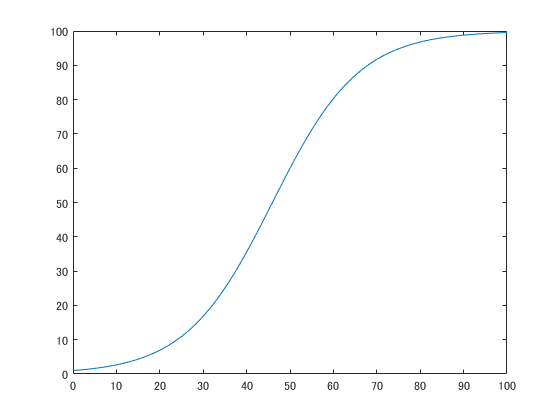

t = 0:0.1:100;
n0 = 1;
k = 100;
r = 0.1;
n = k ./ (1+(k/n0-1).*exp(-r.*t));

plot(t,n);

### ODEソルバーによる解

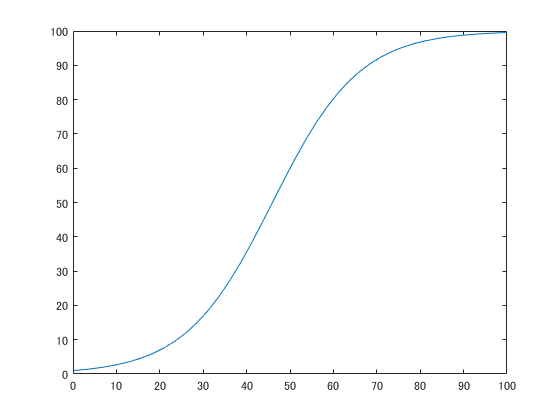

tspan = [0 100];
n0 = 1;
[t,n] = ode45(@logistic, tspan, n0);
plot(t, n);